# Primer parcial

## Señales básicas

Suponga que $x(t)=tcos(2\pi t)$ con $0\leq t \leq5$.

Graficar:

- 
$$x(t)$$


- 
$$x(-t)
$$


- 
$$x(t/5)$$


- 
$$x(1+3t)$$


- 
$$x(-1-3t)$$


Debe hacerse una señal continua y una discreta. El resultado debe tener ejes y leyenda, tal como se muestra a continuación.

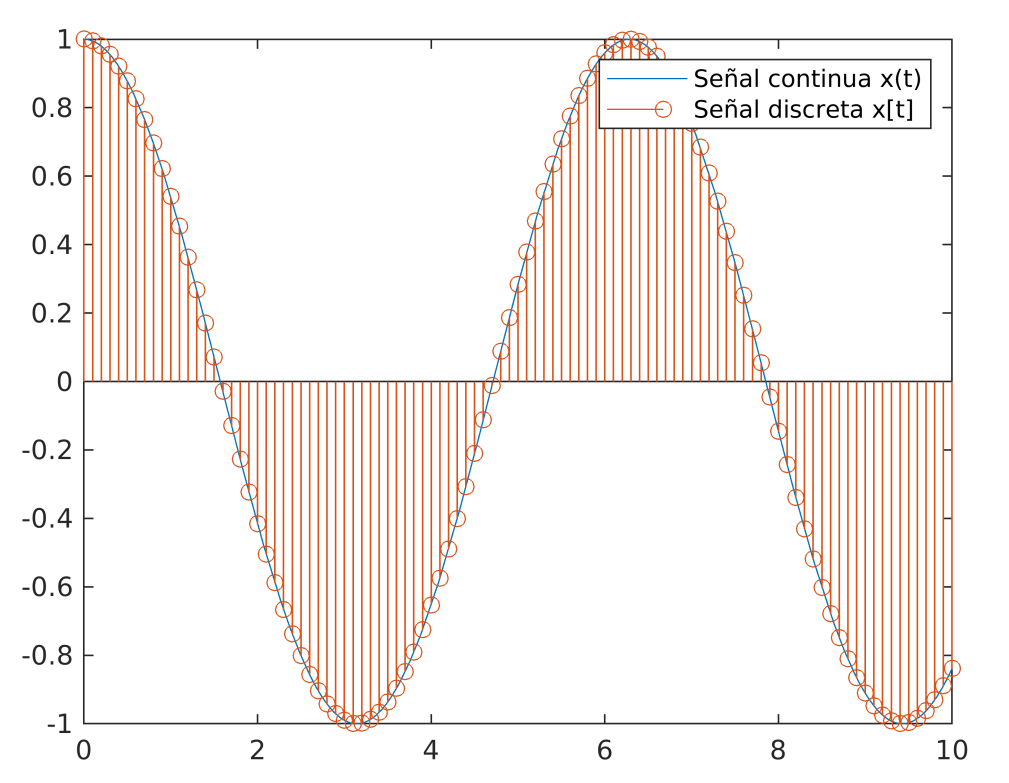

Recomiendo hacer un subplot o usar tiledlayout para agrupar todas las gráficas en un solo figure. Si no es posible, hacer cada gráfica en un figure distinto.

## **Importación de datasets**

Importar los siguientes archivos de de Utils4SP:

- **Sonda_Ace.txt **: Se necesita la herramienta de importación manual. Debe salir una tabla, en donde los nombre de los campos describan el parámetro físico medido, sus unidades y el tipo de variable. Son ~329k lecturas 

            Una vez que el resultado sea satisfactorio, exportar la función con un nombre similar a "importfile_sondaAce.m"

- **ruido.wav: **Debe salir una matriz con las muestras del audio y una variable con la frecuencia de muestreo.

- **IrishNationalTideGauge.csv: **Debe salir una tabla con ~250k lecturas. 

En todos los casos, los datos deben estar disponibles en el Worskpace. Dejar la salida de las funciones habilitadas para ver el resultado.

SondaACE=importfile_sondaAce("../../../Utils4SP/Datasets/Sonda_ACE.txt");
[ruido,fs]=audioread("../../../Utils4SP/Datasets/ruido.wav");
IrishTide=readtable("../../../Utils4SP/Datasets/IrishNationalTideGauge.csv");

## Lectura de archivo .mat

Importar el archivo .mat "E1_PrimerParcial.mat". Incluye los datos anteriores con un poco de preprocesamiento.

## Plots exploratorios

Obtener las siguientes gráfcias para los datos de la sonda Ace.

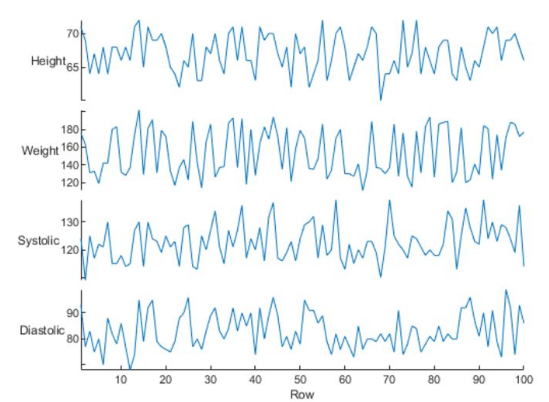  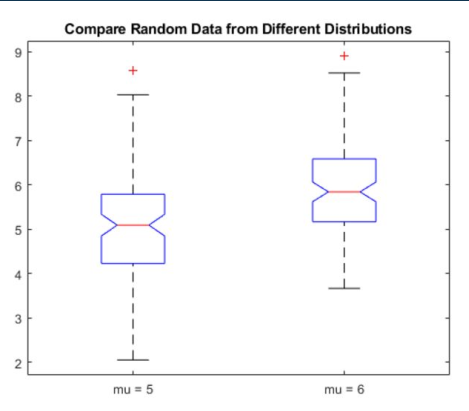 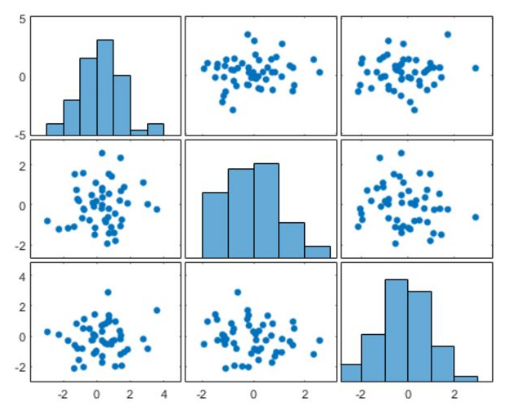

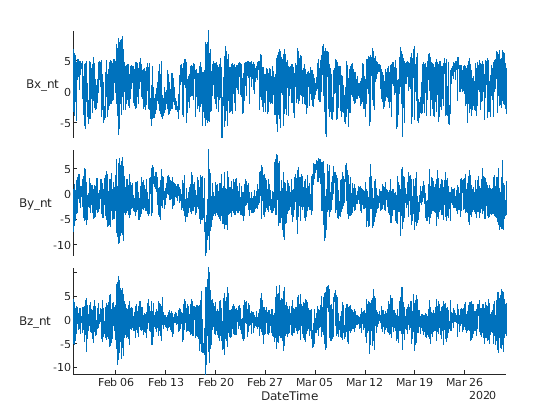

figure
stackedplot(SondaACE,'XVariable','DateTime')

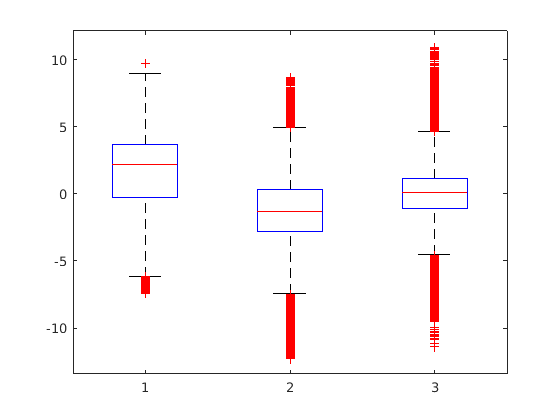


figure
boxplot(SondaACE{:,["Bx_nt" "By_nt" "Bz_nt"]})

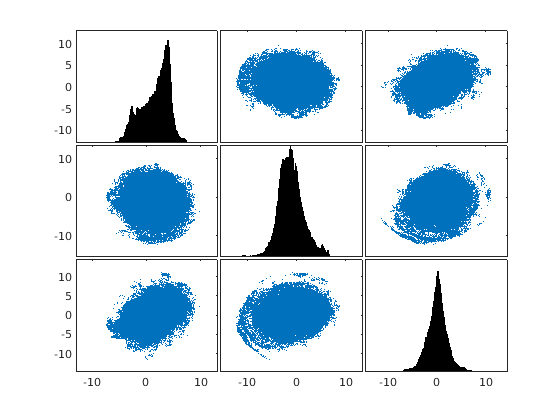


figure
plotmatrix(SondaACE{:,["Bx_nt" "By_nt" "Bz_nt"]})

Obtener las siguientes visualizaciones para la variable "Water_Level_OD_Malin" de la tabla "IrishTide"

Nota: Estas visualizaciones estarán bien ejecutadas pero su resultado será insatisfactorio.

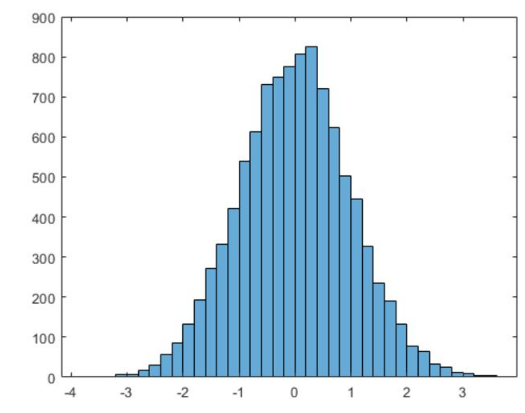 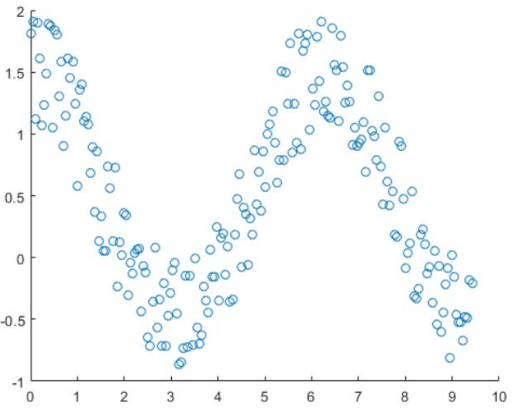

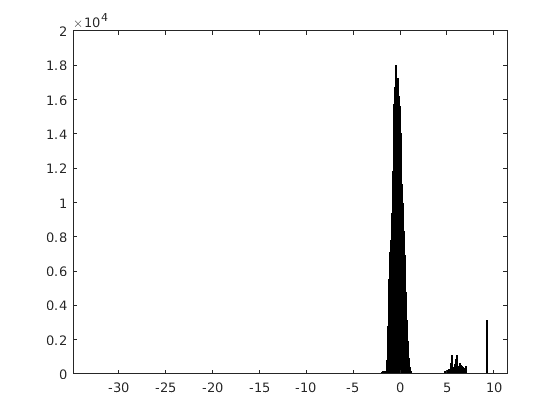

figure
histogram(IrishTide.Water_Level_OD_Malin)

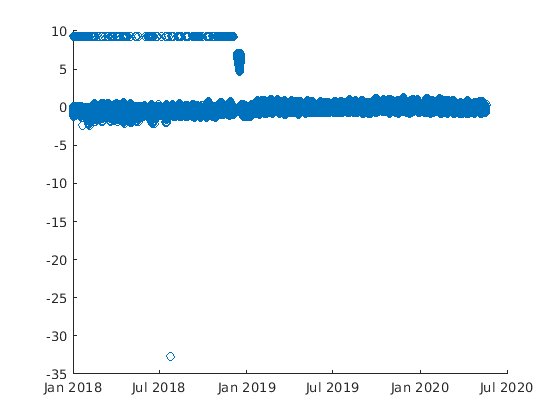


figure
scatter(IrishTide.DateTime,IrishTide.Water_Level_OD_Malin)

## Preprocesamiento 

Diagnosticar el número de NaN's en los datos de la Sonda Ace y de Irish Tide. Una vez diagnosticado, removerlos y probar que ya no hay NaN's.

Nota:¡ No hay que sobreescribir variables!

summary(IrishTide)

Variables:

    DateTime: 249622×1 datetime

        Values:

            Min       2018-01-01T07:12:00Z
            Median    2019-02-26T23:42:30Z
            Max       2020-05-18T06:55:00Z

    Water_Level_OD_Malin: 249622×1 double

        Values:

            Min             -32.758  
            Median          -0.237   
            Max             9.216    
            NumMissing      1        



summary(SondaACE)

Variables:

    DateTime: 329403×1 datetime

        Values:

            Min             30-01-2020 23:00:10.000  
            Median          01-03-2020 10:59:57.000  
            Max             31-03-2020 23:00:00.000  
            NumMissing      3                        

    Bx_nt: 329403×1 double

        Values:

            Min             -7.422  
            Median          2.202   
            Max             9.747   
            NumMissing      3       

    By_nt: 329403×1 double

        Values:

            Min             -12.265  
            Median          -1.286   
            Max             8.671    
            NumMissing      3        

    Bz_nt: 329403×1 double

        Values:

            Min             -11.38  
            Median          0.094   
            Max             10.972  
            NumMissing      3       




IrishTide_noNans=rmmissing(IrishTide);
SondaAce_noNans=rmmissing(SondaACE);


Una vez removidos los Nans, obtener la siguiente vizualizacion de IrishTides:

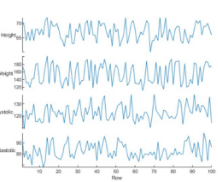

¿Los resultados ya sonsatisfactorios? Discute el por qué sí o por qué no.

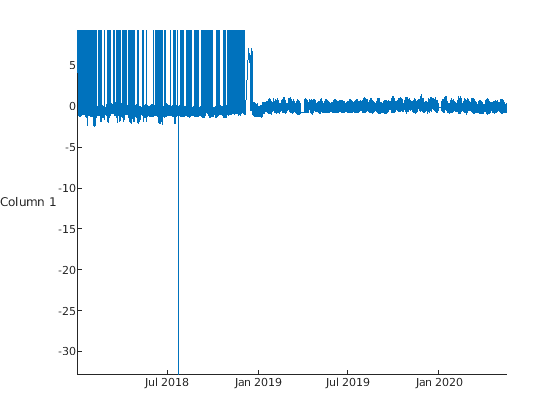

figure
stackedplot(IrishTide_noNans.DateTime,IrishTide_noNans.Water_Level_OD_Malin)

Usando el criterio de la sección pasada, elegir una porción de datos entre el 6 de Mayo del 2020 a las 6am y la última lectura disponible en IrishTide. Con esos datos, hacer las siguientes visualizaciones.

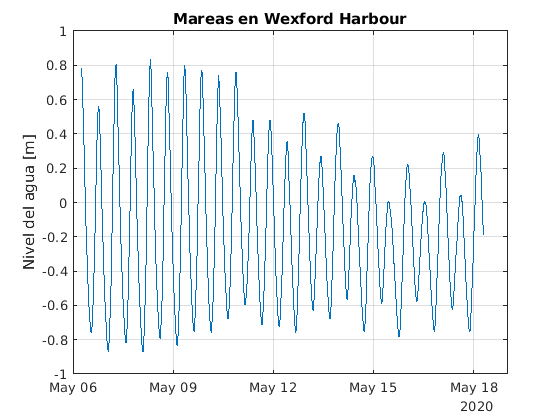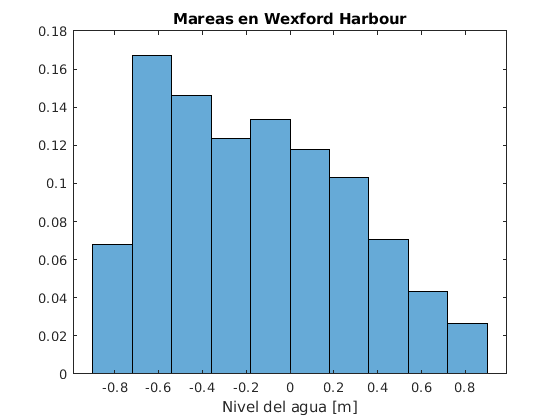

index= IrishTide_noNans.DateTime>datetime(2020,05,06,06,00,00);

plot(IrishTide_noNans.DateTime(index),IrishTide_noNans.Water_Level_OD_Malin(index))
grid on
ylabel("Nivel del agua [m]")
title("Mareas en Wexford Harbour")



figure
histogram(IrishTide_noNans.Water_Level_OD_Malin(index),10,'Normalization',"probability")
title("Mareas en Wexford Harbour")
xlabel("Nivel del agua [m]")

## Estadística 101

Obtener el la mediana, promedio, primer cuartil y tercer cuartil para los datos de IrishTide entre el 6 de Mayo del 2020 a las 6am y la última lectura  disponible. Dibujar las líneas de estas cantidades sobre el histograma y la serie de tiempo.

De la siguiente figura, discute por qué el valor del promedio y de la mediana difieren. 

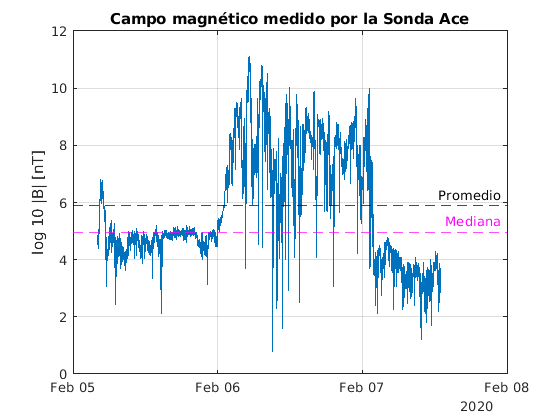

- Hacer una serie de tiempo e histograma de ruido. 

- Poner con una línea el promedio y sus deviaciones a 1 y 2 sigma sobre la serie de tiempo y el histograma.

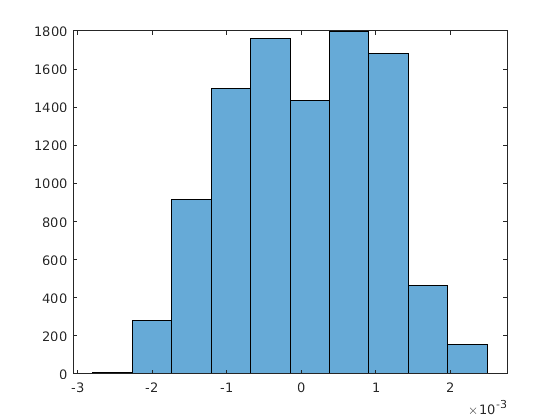

figure
plot(ruido)

figure
histogram(ruido,10)

- Ajustar una función gaussiana (El tipo de ajuste se llama "gauss1") a la distribución de datos de ruido. 

- Mostrar el valor de $r^2$ y discutir si es un buen ajuste o no.

- Plotear el ajuste encima del histograma.

El resultado final debe verse así:

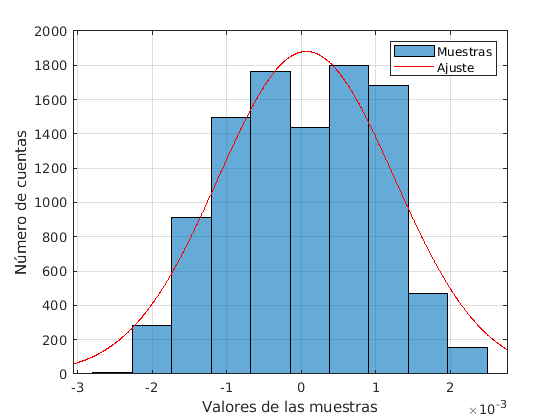

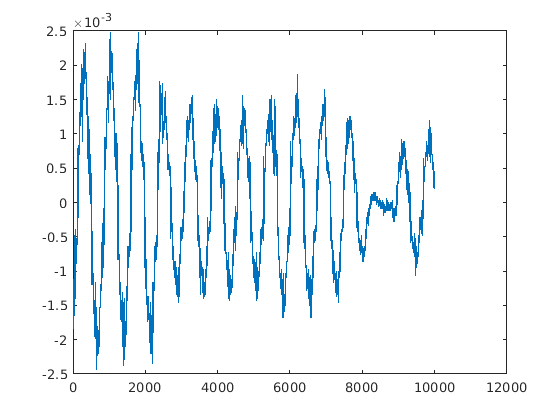

gaussfit =      General model Gauss1:
     gaussfit(x) =  a1*exp(-((x-b1)/c1)^2)
     Coefficients (with 95% confidence bounds):
       a1 =        1881  (1441, 2320)
       b1 =   7.002e-05  (-0.0002496, 0.0003896)
       c1 =    0.001677  (0.001205, 0.002149)

gof = struct with fields:
           sse: 6.2394e+05
       rsquare: 0.8650
           dfe: 7
    adjrsquare: 0.8264
          rmse: 298.5547


%Usar esta línea de código antes
h=histogram(ruido,10);
y=h.BinCounts';
x=h.BinEdges+h.BinWidth/2;
x=x(1:end-1)';

%A partir de aquí, usar el ajuste usando las variables x & y
[gaussfit,gof]=fit(x,y,'gauss1')


figure
histogram(ruido,10)
hold on
plot(gaussfit)
hold off
legend("Muestras","Ajuste")
ylabel("Número de cuentas")
xlabel("Valores de las muestras")
grid on

## Extra

dateTimeVec=datetime(IrishTide.time,'Format','yyyy-MM-dd''T''HH:mm:ss''Z');

IrishTide.DateTime=dateTimeVec;


IrishTide(:,["time" "station_id" "latitude" "longitude" "QC_Flag" "Water_Level_LAT"])=[];
IrishTide = movevars(IrishTide, 'DateTime', 'Before', 'Water_Level_OD_Malin');

index=...
    SondaAce_noNans.DateTime>datetime(2020,02,05,4,0,0) &...
    SondaAce_noNans.DateTime<datetime(2020,02,7,13,0,0); 
    
Bmag=sqrt(SondaAce_noNans.Bx_nt(index).^2+SondaAce_noNans.By_nt(index).^2+SondaAce_noNans.Bz_nt(index).^2);
figure
plot(SondaAce_noNans.DateTime(index),Bmag)
hold on
yline(median(Bmag),'--m','Mediana')
yline(mean(Bmag),'--k','Promedio')
hold off
grid on
ylabel("log 10 |B| [nT]")
title("Campo magnético medido por la Sonda Ace")

ruido=ruido(50000:60000,:);